addpath('./datos')
addpath('./funciones')

**Tarea 5a: **Utilizando como datos la matriz training

load('Tarea4.mat')

umbral = 0.01;
display=0; %no sacar grafica

VQini= [];

load('traindata.mat')
if isempty(gcp('nocreate'))
parpool;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 8).


Obtén con Kmeans cuantificadores vectoriales de 1 a 16 bits (umbral = 0,01).

for nbits = 1 : 16
    horaInicial = clock;
    [VQ, vDist no_asig] = Kmeans (training, nbits, VQini, umbral, display);
    horaFinal=clock;
    vectorHorasEstimacion(nbits,:) = etime(horaFinal, horaInicial);

Almacena los 16 VQs en una única matriz VQt de forma que las dos primeras filas se correspondan con los centroides del VQ de 1 bit, las cuatro siguientes con los centroides del VQ de 2 bits, etc.

    if nbits == 1
        VQt = VQ;
    else 
        VQt = vertcat(VQt, VQ);
    end
end

Registra el tiempo que tarda en estimarse cada uno de los 16 VQs y represéntalo en función del número de bits.

horasEstimacion = sum(vectorHorasEstimacion)

horasEstimacion = 380.1540

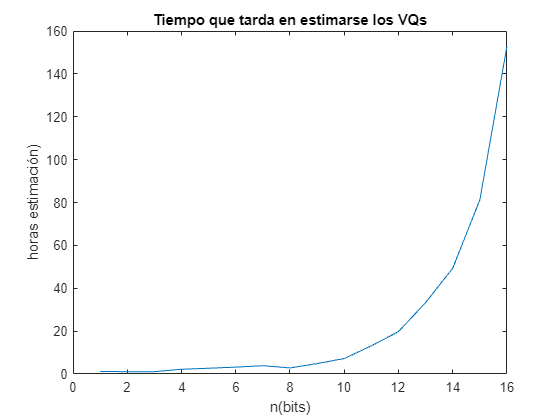


n=1:1:16;
figure
plot(n,vectorHorasEstimacion); 
grid
xlabel('n(bits)')
ylabel('horas estimación)')
title("Tiempo que tarda en estimarse los VQs")
grid

Guarda la matriz VQt y los tiempos registrados en el fichero VQt.mat.

save ('VQt.mat', 'VQt', 'vectorHorasEstimacion');

save 5a.mat

**Tarea 5b:**

load ('VQt.mat', 'VQt', 'vectorHorasEstimacion');

[valores_training_5s, fs_training_5s] = audioread('tvg_training_5s.wav');


for nbits = 1:1:16
    
    % Extraigo de la matriz VQt las filas correspondientes al VQ de nbits
    % de la iteración correspondiente
    if nbits == 1
        filainicial = 1;
        filafinal = 2;
    else 
        filainicial = filainicial + 2^(nbits-1);
        filafinal = filainicial + 2^nbits - 1;      
    end
    
    VQi = VQt (filainicial:filafinal, :);
    % -------------------------------------------------
    
    [y_training_5s, Dist_training_5s] = VQuantize(valores_training_5s,VQi);
    
    columna = 0; %para cambiar entre una columna y otra
    fila = 1;
    training_5s_cat=[];
    for i=1:length(valores_training_5s)
        if columna == 0 %impar
            training_5s(fila, 1) = y_training_5s (i);
            columna = 1;
        else %par
            training_5s(fila, 2) = y_training_5s (i);
            columna = 0;
            fila = fila + 1;
        end
    end
    
    
    dataq = VQuantize (training_5s, VQi);
   
    
    % Reordeno dataq en fila
    columna = 0; 
    fila = 1;
    for i=1:length(dataq)
        if columna == 0 %impar
            dataq_reordenado (i) = dataq(fila, 1);
            columna = 1;
        else %par
            dataq_reordenado (i) = dataq(fila, 2);
            columna = 0;
            fila = fila + 1;
        end
    end
    [F,C]=size(training_5s);
    for i=1:F
       a=training_5s(i,:);
        training_5s_cat = horzcat(training_5s_cat,a);
    end
    SNRq_training = SNR(training_5s_cat, dataq_reordenado);
   
end

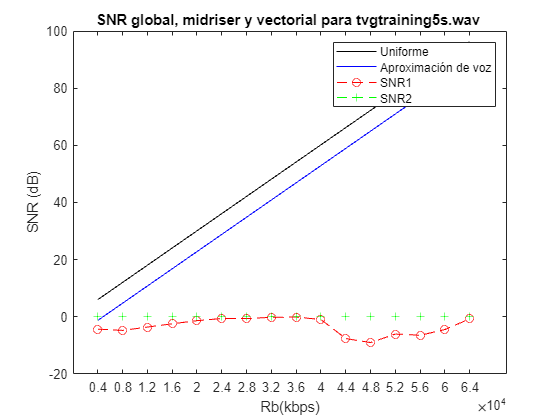

xsc=1;
    [training_5s_QMR, training_5s_QMR] = qmidriser(training_5s_cat, xsc, 8);

fs=8*10^3;
    
n=1:1:16;
Rb = 8*10^3*(n/2);      % Rb entre [4 kB - 64 kB]
figure
plot(Rb,6.02*n,'k')
hold on;
plot(Rb,6.02*n-7.27,'b')
hold on;
plot(Rb,SNRq_training(1:length(Rb)),'r--o');
ax = gca; 
ax.XTick = Rb; 
grid
hold on;plot(Rb,training_5s_QMR(1,length(Rb)),'g--+');
ax = gca; 
ax.XTick = Rb; 
xlabel('Rb(kbps)')
ylabel('SNR (dB)')
legend('Uniforme','Aproximación de voz', 'SNR1','SNR2')
title("SNR global, midriser y vectorial para tvgtraining5s.wav ")
grid

**Tarea 5c:**

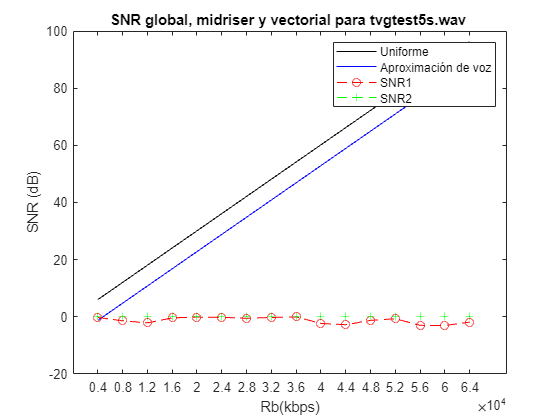

load ('VQt.mat', 'VQt', 'vectorHorasEstimacion');

[valores_test_5s, fs_test_5s] = audioread('tvg_test_5s.wav');


for nbits = 1:1:16
    
    % Extraigo de la matriz VQt las filas correspondientes al VQ de nbits
    % de la iteración correspondiente
    if nbits == 1
        filainicial = 1;
        filafinal = 2;
    else 
        filainicial = filainicial + 2^(nbits-1);
        filafinal = filainicial + 2^nbits - 1;      
    end
    
    VQi = VQt (filainicial:filafinal, :);
    % -------------------------------------------------
    
    [y_test_5s, Dist_test_5s] = VQuantize(valores_test_5s,VQi);
    
    columna = 0; %para cambiar entre una columna y otra
    fila = 1;
    for i=1:length(valores_test_5s)
        if columna == 0 %impar
            test_5s(fila, 1) = y_test_5s (i);
            columna = 1;
        else %par
            test_5s(fila, 2) = y_test_5s (i);
            columna = 0;
            fila = fila + 1;
        end
    end
    
    
    dataq = VQuantize (test_5s, VQi);
   
    
    % Reordeno dataq en fila
    columna = 0; 
    fila = 1;
    for i=1:length(dataq)
        if columna == 0 %impar
            dataq_reordenado (i) = dataq(fila, 1);
            columna = 1;
        else %par
            dataq_reordenado (i) = dataq(fila, 2);
            columna = 0;
            fila = fila + 1;
        end
    end
    test_5s_cat=[];
    [F,C]=size(test_5s);
    for i=1:F
       a=test_5s(i,:);
        test_5s_cat = horzcat(test_5s_cat,a);
    end
    SNRq_test = SNR(test_5s_cat, dataq_reordenado);
   
end
xsc=1;
    [test_5s_QMR, test_5s_QMR] = qmidriser(test_5s_cat, xsc, 8);

fs=8*10^3;
    
n=1:1:16;
Rb = 8*10^3*(n/2);      % Rb entre [4 kB - 64 kB]
figure
plot(Rb,6.02*n,'k')
hold on;
plot(Rb,6.02*n-7.27,'b')
hold on;
plot(Rb,SNRq_test(1:length(Rb)),'r--o');
ax = gca; 
ax.XTick = Rb; 
grid
hold on;plot(Rb,test_5s_QMR(1,length(Rb)),'g--+');
ax = gca; 
ax.XTick = Rb; 
xlabel('Rb(kbps)')
ylabel('SNR (dB)')
legend('Uniforme','Aproximación de voz', 'SNR1','SNR2')
title("SNR global, midriser y vectorial para tvgtest5s.wav ")
grid